%problem 15
clear
num=10000

num = 10000

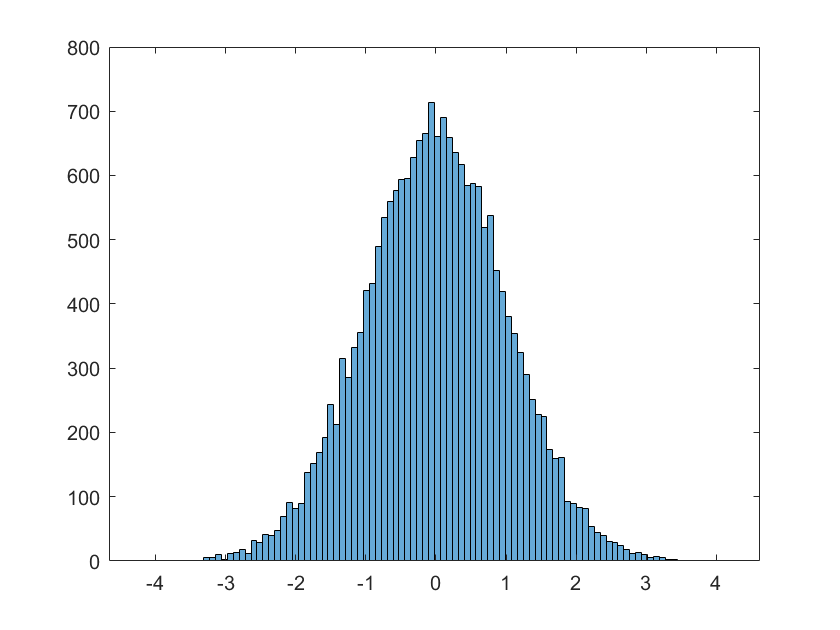

u = ones(num,1);

sig=1;
mu=0;
x = linspace(mu-0.6*sig,mu+0.6*sig,num);

F = 1/(sig*sqrt(2*pi))*exp(-0.5*((x-mu)/(sig)).^2);
c = max(F'./u);

X = zeros(num,1);
j=1;
while j<num   
    y=rand;
    y=-log(y);
    u=rand;

    if u <= exp(-(y-1)^2/2)
        X(j)=y;
        j = j + 1;
    end
end

X = [X -X];
histogram(X,100)